# Sprawozdanie 6

Karolina Piotrowska

### Zadanie 1

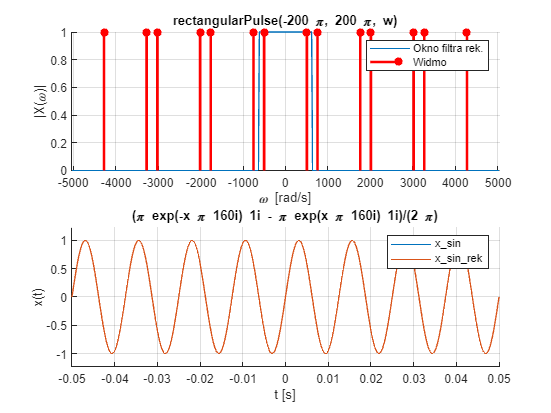

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t);
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

### Zadanie 2

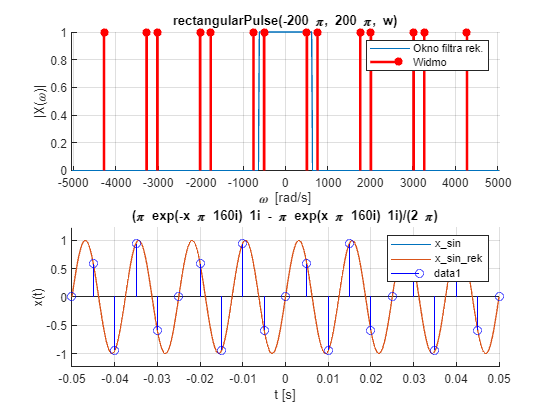

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t);
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);
stem(wezly, wezly_val, 'b');

### Zadanie 3

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
S = [1/5, 6/5, 11/5, 16/5, 4/5, 9/5, 14/5]

S =     0.2000    1.2000    2.2000    3.2000    0.8000    1.8000    2.8000


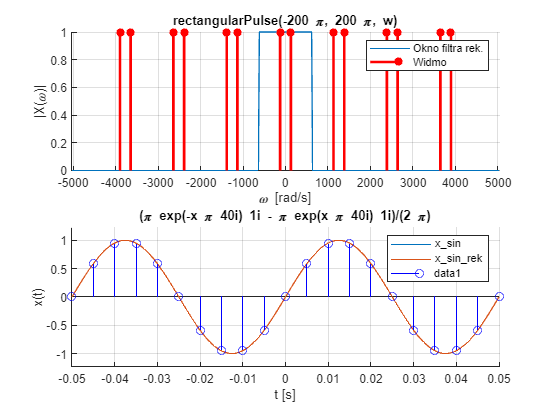

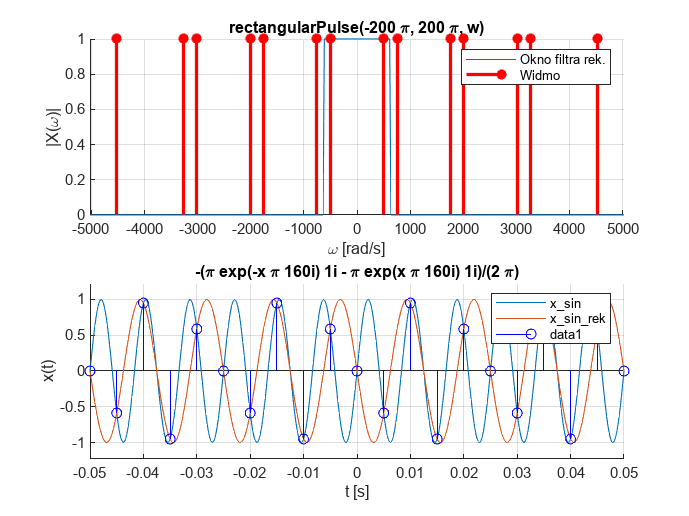

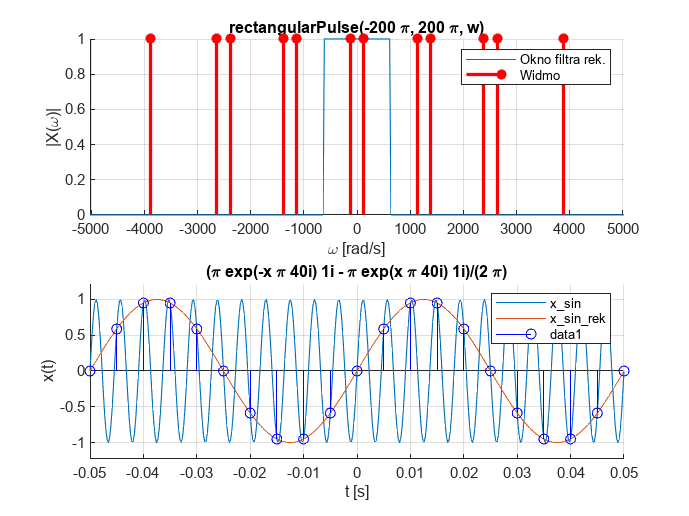

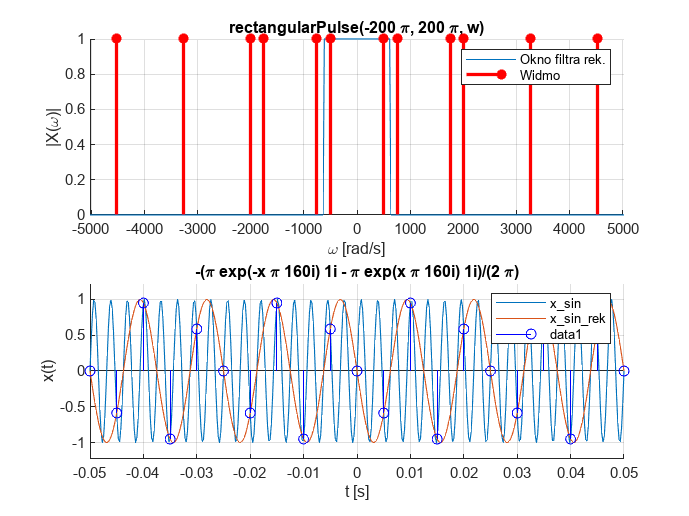

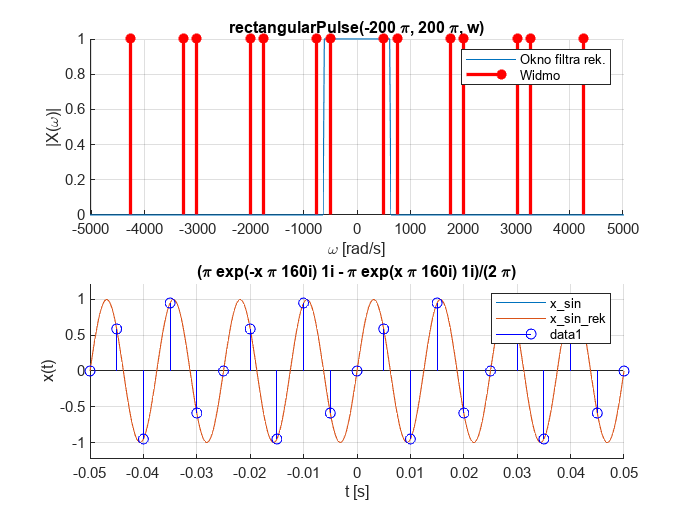

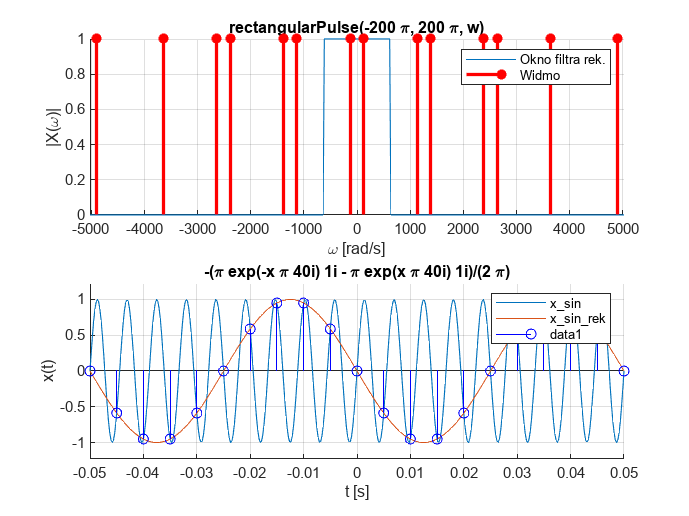

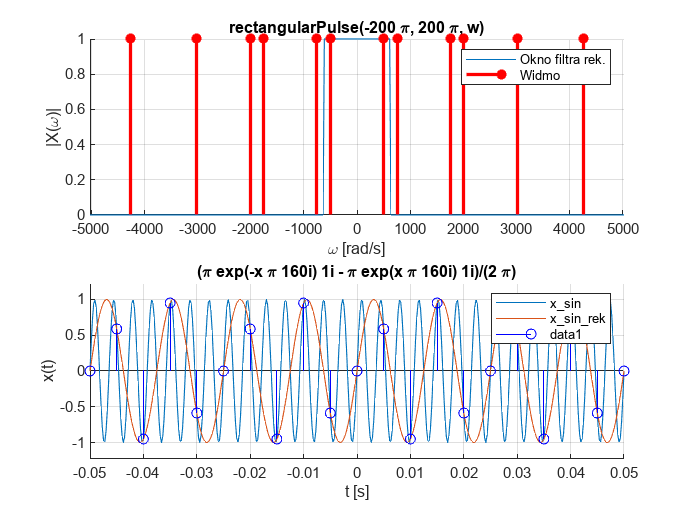

for s = S
    ws = s*wg;
    x_sin = sin(ws*t);
    X_FT_sin_org = fourier(x_sin);
    X_FT_sin = X_FT_sin_org + ... % oryginal widma
       symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
       subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
    x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
    BND_t = [-10/fp;10/fp];
    BND_w = [-4*wp;4*wp];
    w_SMP = [BND_w(1):wp/10:BND_w(2)];
    figure; subplot(2,1,1); hold on; grid on;
    ezplot(FILT_FT,BND_w); %okno filtru rek.
    v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
    n = find(abs(v_num) == Inf);
    stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    subplot(2,1,2); hold on; grid on;
    ezplot(x_sin, BND_t);
    ezplot(x_sin_rek, BND_t) % syg. odtworzony
    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_sin','x\_sin\_rek');
    wezly = BND_t(1) : 1/fp : BND_t(2);
    wezly_val = subs(x_sin_rek, x, wezly);
    stem(wezly, wezly_val, 'b');
    hold off
end

Gdy częstotliwość próbkowania jest mniejsza niż dwukrotność częstotliwości sygnału próbkowanego, rekonstruowany jest sygnał o częstotliwości zmniejszonej względem próbkowanego. Oba sygnały zawsze przechodzą przez wszystkie węzły próbkowania. 

### Zadanie 4

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
S = [1/5, 6/5, 11/5, 16/5, 4/5, 9/5, 14/5]

S =     0.2000    1.2000    2.2000    3.2000    0.8000    1.8000    2.8000


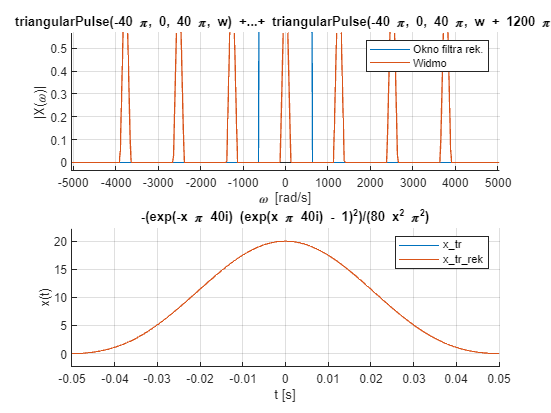

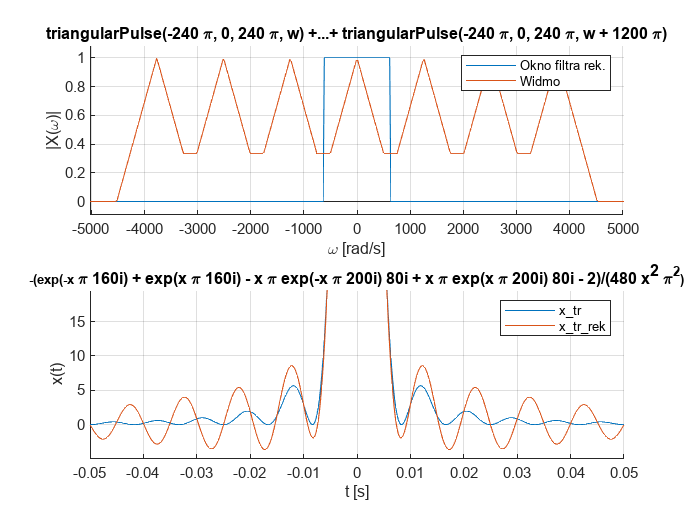

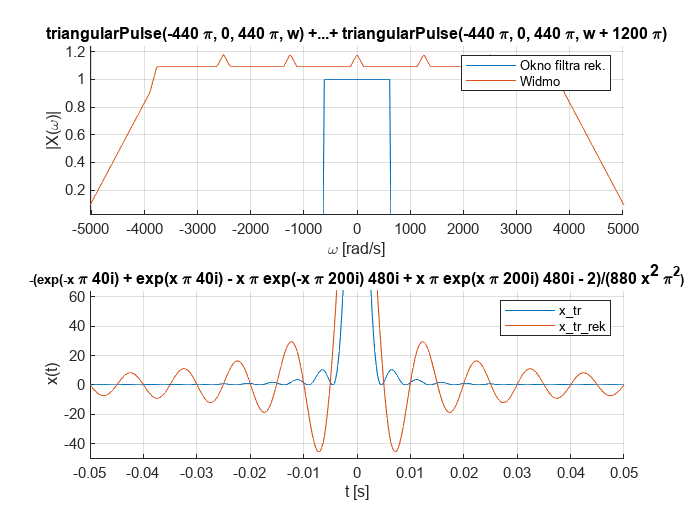

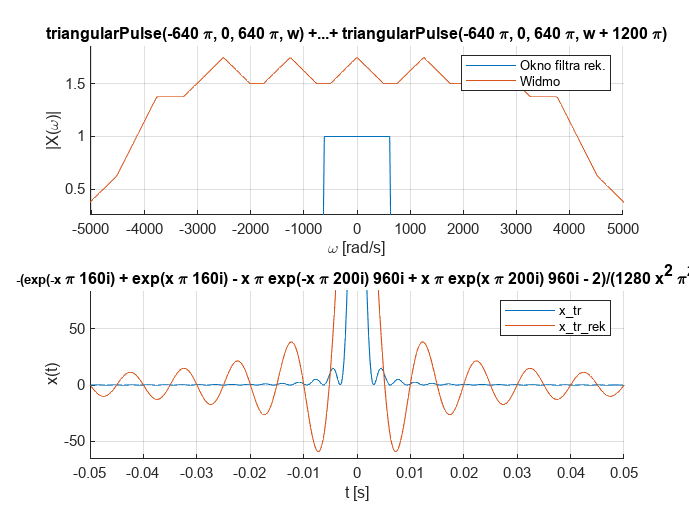

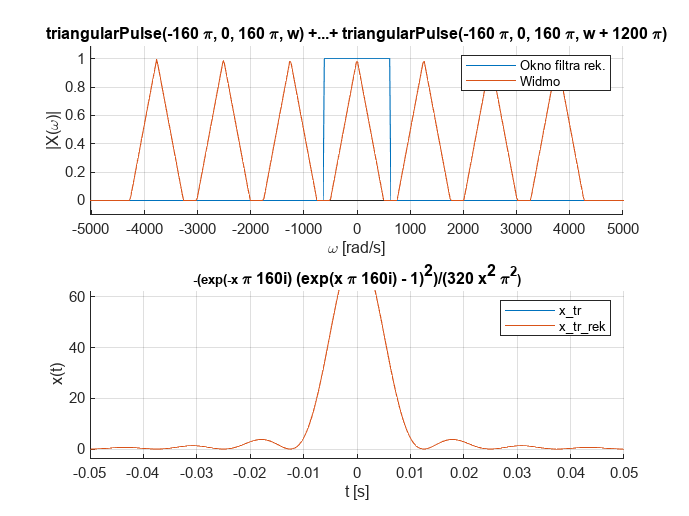

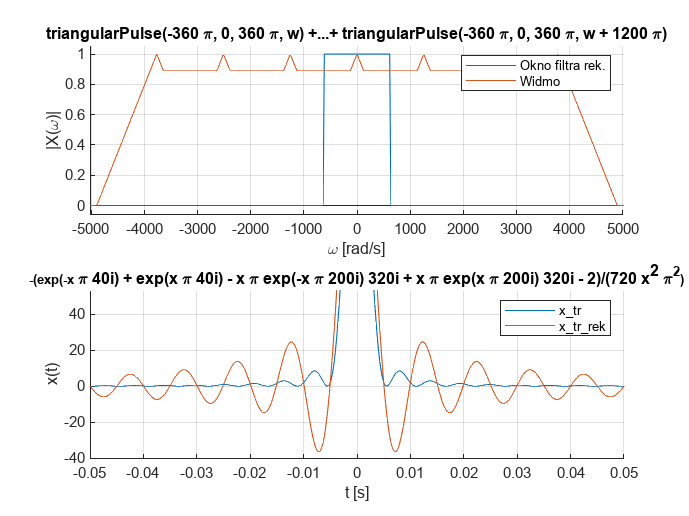

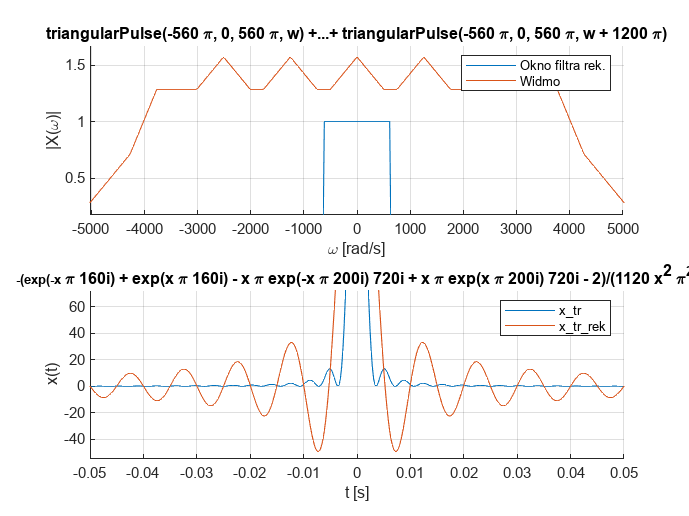

for s = S
    ws = s*wg;
    x_tr = ifourier(triangularPulse(-ws,ws,w));
    X_FT_tr_org = triangularPulse(-ws,ws,w);
    X_FT_tr = X_FT_tr_org + ... % oryginal widma
       symsum((subs(X_FT_tr_org, w, w - K*wp ) + ... % 3 aliasy lewe
       subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
    x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
    BND_t = [-10/fp;10/fp];
    %t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
    BND_w = [-4*wp;4*wp];
    w_SMP = [BND_w(1):wp/10:BND_w(2)];
    figure; subplot(2,1,1); hold on; grid on;
    ezplot(FILT_FT,BND_w); %okno filtru rek.
    ezplot(X_FT_tr,BND_w)
    v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
    n = find(abs(v_num) == Inf);
    stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    subplot(2,1,2); hold on; grid on;
    ezplot(x_tr, BND_t);
    ezplot(x_tr_rek, BND_t) % syg. odtworzony
    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_tr','x\_tr\_rek');
    hold off
end

Gdy widmo jest węższe niż okno filtra, sygnał jest rekonstruowany poprawnie. W przeciwnym wypadku, aliasy zaczynają nachodzić na siebie, przez co rekonstrukcja sygnału jest niepoprawna.

### Zadanie 5

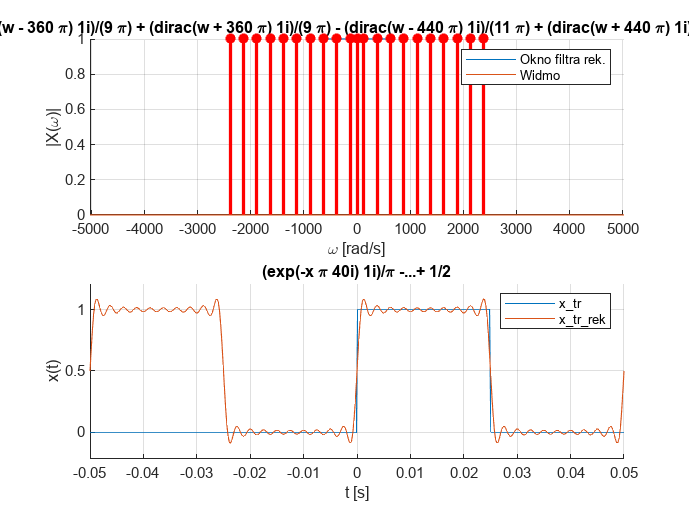

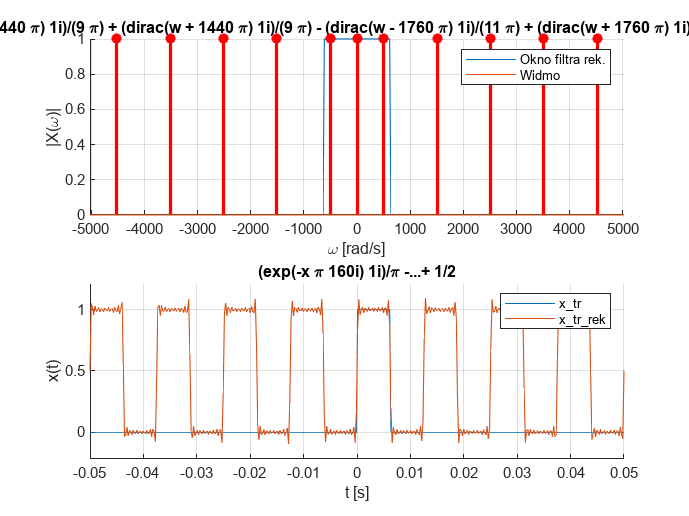

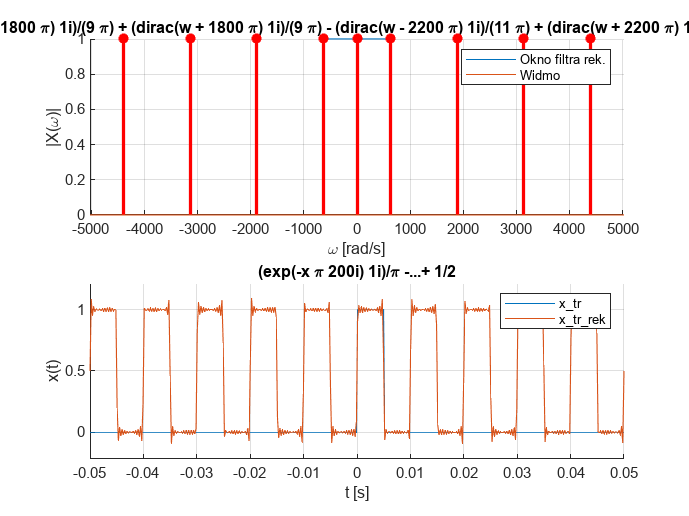

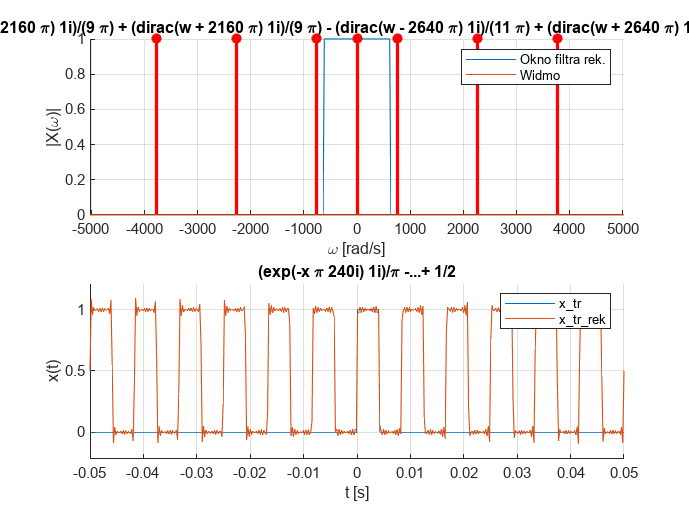

clear; close all;
syms t x w;
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
S = [1/5, 4/5, 1, 6/5];
for s = S
    ws = s*wg;
    fs = s*fg;
    T = 1/fs;
    x = rectangularPulse(0, T/2, t);    
    NT = 20;
    sumX = 0;
    ind=-NT:NT;
    BND = [-T/2, T/2];
    for n = ind
        Xn = 1/T*int(x*exp(-1i*ws*n*t),t,BND);
        sumX = sumX + Xn * dirac(w - n*ws);
    end 
    X_FT_org = 2*pi * sumX;
    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
    x_tr_rek = ifourier(X_FT_org);
    BND_t = [-10/fp;10/fp];
    BND_w = [-4*wp;4*wp];
    w_SMP = [BND_w(1):wp/10:BND_w(2)];
    figure; subplot(2,1,1); hold on; grid on;
    ezplot(FILT_FT,BND_w); %okno filtru rek.
    ezplot(X_FT_org,BND_w)
    v_num = abs(double(subs(X_FT_org, w, w_SMP)));
    n = find(abs(v_num) == Inf);
    stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    subplot(2,1,2); hold on; grid on;
    ezplot(x, BND_t);
    ezplot(x_tr_rek, BND_t) % syg. odtworzony
    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_tr','x\_tr\_rek');
    hold off
end

W celu rekonstrukcji sygnału prostokątnego częstotliwość próbkowania powinna być wielokrotnie większa od częstotliwości sygnału prostokątnego.